##     EEE 321 Signals and Systems - Lab 1 Report - Tuna Şahin, 22201730

##     Question 1-a:

Calculate the values of the function:

n = linspace(0,127,128);
x1 = 3*cos(0.13*pi*n+0.5);

Write the array x1 containing the values of the function to the text file 'lab1values.txt'

x1read = readwrite2file(x1,'1');
txt1 = sprintf('x1[3] = %f | x1[7] = %f | x1[114] = %f | x1[127] = %f ',x1read(4),x1read(8),x1read(115),x1read(128));
disp(txt1)

x1[3] = -0.461435 | x1[7] = -2.929477 | x1[114] = -2.993570 | x1[127] = -1.520264 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

The computer stores numbers in a text file providing seven significant digits along with its exponent in scientific notation. This would make our resolution 0.000001 in our case. However, in matlab, the smallest possible double number is given as:

disp(realmin) % = 2.2251e-308

  2.2251e-308



Which would make it our true resolution.

###     Question 1-b:    

Plot the function as a stem plot:

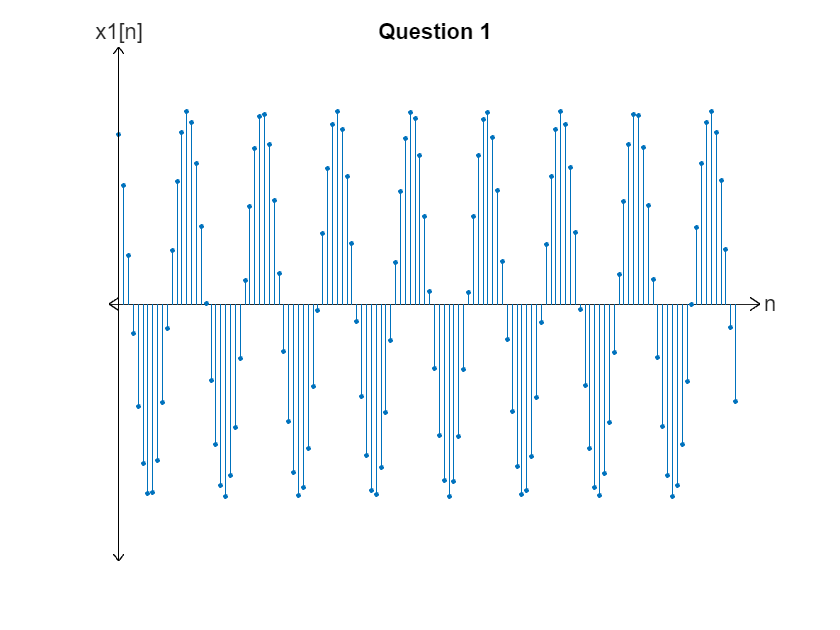

hold on
stem(n,x1,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-4 4])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')


plot([130 132],[0.1 0],'k')
plot([130 132],[-0.1 0],'k')
plot([-2 0],[0 0.1],'k')
plot([-2 0],[0 -0.1],'k')

plot([0 0],[-4 4],'k')
plot([-1 0],[3.9 4],'k')
plot([1 0],[3.9 4],'k')
plot([-1 0],[-3.9 -4],'k')
plot([1 0],[-3.9 -4],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.2; % change vertical position of ylabel.

label_h2 = ylabel('x1[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 4.05; % change vertical position of ylabel.
title('Question 1');
hold off

$\omega =0\ldotp 13\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200}{13}k=200$$


if we add N to any t we can see that they are identical:

txt1period = sprintf('x1[1] = %f = x1[201] = %f',cos(0.13*pi*1+0.5),cos(0.13*pi*201+0.5));
disp(txt1period)

x1[1] = 0.615003 = x1[201] = 0.615003


##     Question 2:

Calculate the values and perform the write to and read from file operations:

x2 = cos(2.2*pi*n);
x2read = readwrite2file(x2,'2');
txt2 = sprintf('x2[3] = %f | x2[7] = %f | x2[114] = %f | x2[127] = %f ',x2read(4),x2read(8),x2read(115),x2read(128));
disp(txt2)

x2[3] = -0.309017 | x2[7] = -0.309017 | x2[114] = -0.809017 | x2[127] = -0.309017 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

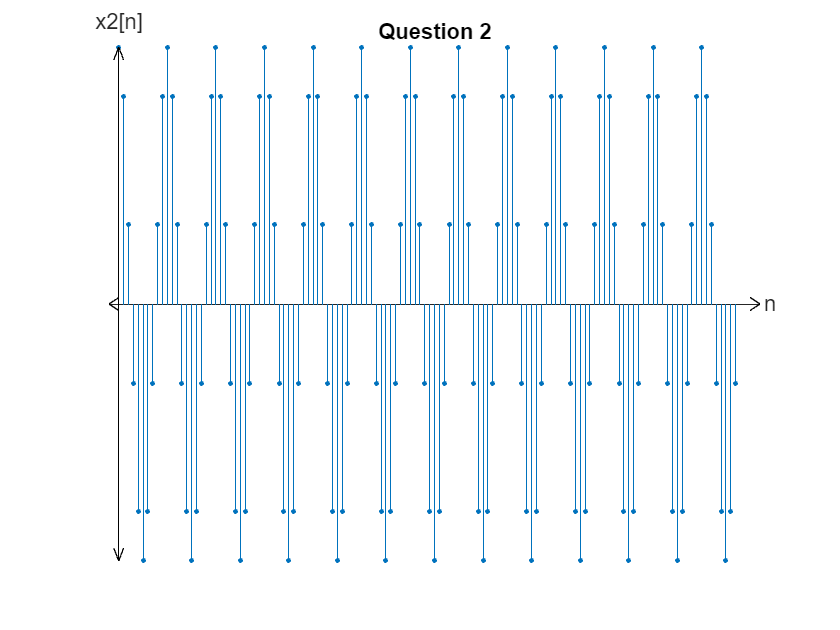

stem(n,x2,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x2[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 2');
hold off

$\omega =2\ldotp 2\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;20}{22}k=10$$


if we add N to any t we can see that they are identical:

txt2period = sprintf('x2[1] = %f = x2[11] = %f',cos(2.2*pi*1),cos(2.2*pi*11));
disp(txt2period)

x2[1] = 0.809017 = x2[11] = 0.809017


##     Question 3:

Calculate the values and perform the write to and read from file operations:

x3 = cos(-1.8*pi*n);
x3read = readwrite2file(x3,'3');
txt3 = sprintf('x3[3] = %f | x3[7] = %f | x3[114] = %f | x3[127] = %f ',x3read(4),x3read(8),x3read(115),x3read(128));
disp(txt3)

x3[3] = -0.309017 | x3[7] = -0.309017 | x3[114] = -0.809017 | x3[127] = -0.309017 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

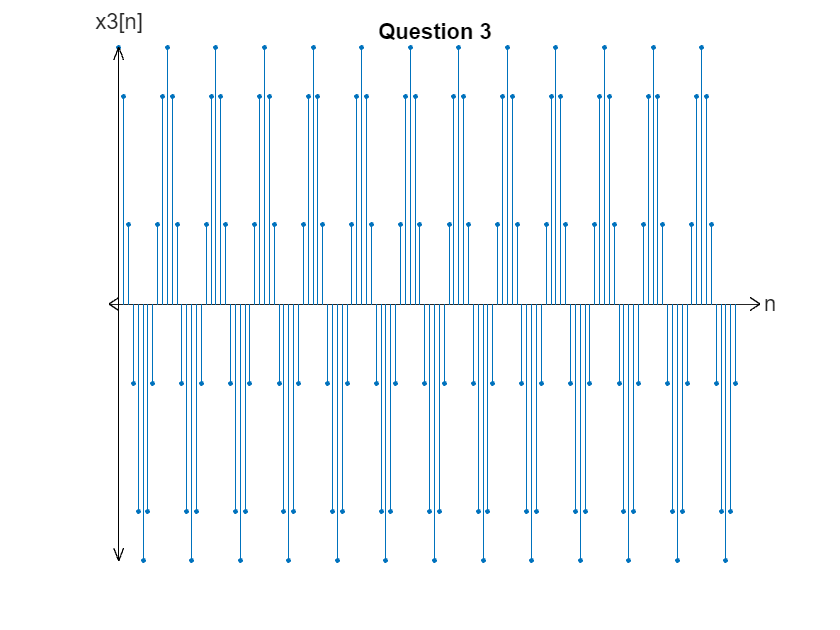

stem(n,x3,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x3[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 3');
hold off

$\omega =1\ldotp 8\pi \;\textrm{rad}$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;20}{18}k=10$$


if we add N to any t we can see that they are identical:

txt3period = sprintf('x3[1] = %f = x1[11] = %f',cos(-1.8*pi*1),cos(-1.8*pi*11));
disp(txt3period)

x3[1] = 0.809017 = x1[11] = 0.809017


###     Comment on Questions 2 & 3:

We can realise that even though the initial value of $\omega \;$is different in questions 2 & 3, their period and $\omega \;$values are actually the same. This is because the value that makes the period an integer is also their gcd(Greatest Common Divisor). We can also notice that their values are identical. This can be explained with the following operations:

$f\left(t\right)=\cos \left(2\ldotp 2\pi \;t\right)=\cos \left(-1\ldotp 8\pi \;t+4\pi \;t\right),$$\forall \;t\in N$ this expression is equal to $\cos \left(-1\ldotp 8\pi \;t\right)$. Therefore the signals are identical.

##     Question 4:

Calculate the values and perform the write to and read from file operations:

x4 = cos(0.26*pi*n);
x4read = readwrite2file(x4,'4');
txt4 = sprintf('x4[3] = %f | x4[7] = %f | x4[114] = %f | x4[127] = %f ',x4read(4),x4read(8),x4read(115),x4read(128));
disp(txt4)

x4[3] = -0.770513 | x4[7] = 0.844328 | x4[114] = 0.425779 | x4[127] = -0.998027 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

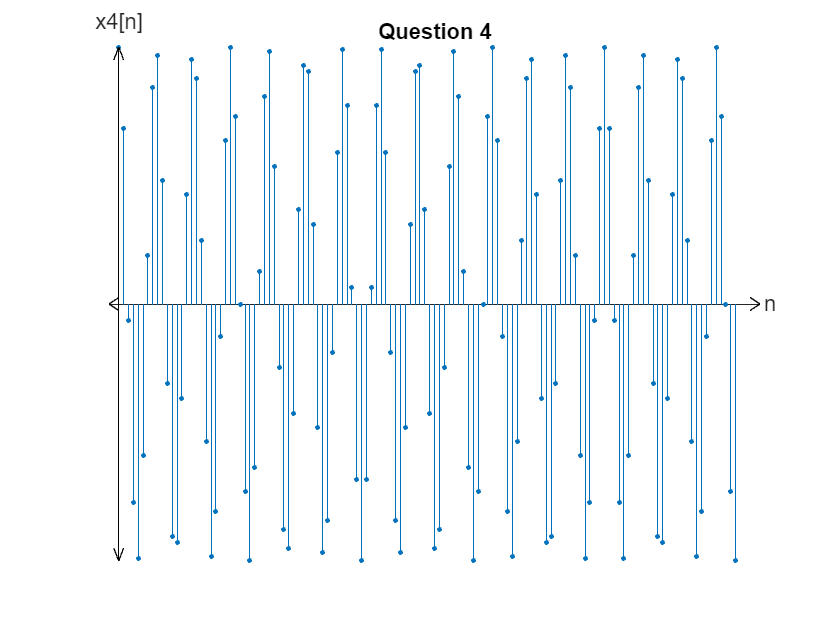

stem(n,x4,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x4[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 4');
hold off

$\omega =0\ldotp 26\pi \;\textrm{rad}$however this is a discrete signal. Therefore to compute the value of $N$we can do the following calculations:


$$N=\frac{\;200}{26}k=100$$


if we add N to any t we can see that they are identical:

txt4period = sprintf('x4[1] = %f = x4[101] = %f',cos(0.26*pi*1),cos(0.26*pi*101));
disp(txt4period)

x4[1] = 0.684547 = x4[101] = 0.684547


##     Question 5:

Calculate the values and perform the write to and read from file operations:

x5 = cos(0.26*pi*n+0.7);
x5read = readwrite2file(x5,'5');
txt5 = sprintf('x5[3] = %f | x5[7] = %f | x5[114] = %f | x5[127] = %f ',x5read(4),x5read(8),x5read(115),x5read(128));
disp(txt5)

x5[3] = -0.999961 | x5[7] = 0.990967 | x5[114] = 0.908560 | x5[127] = -0.722882 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

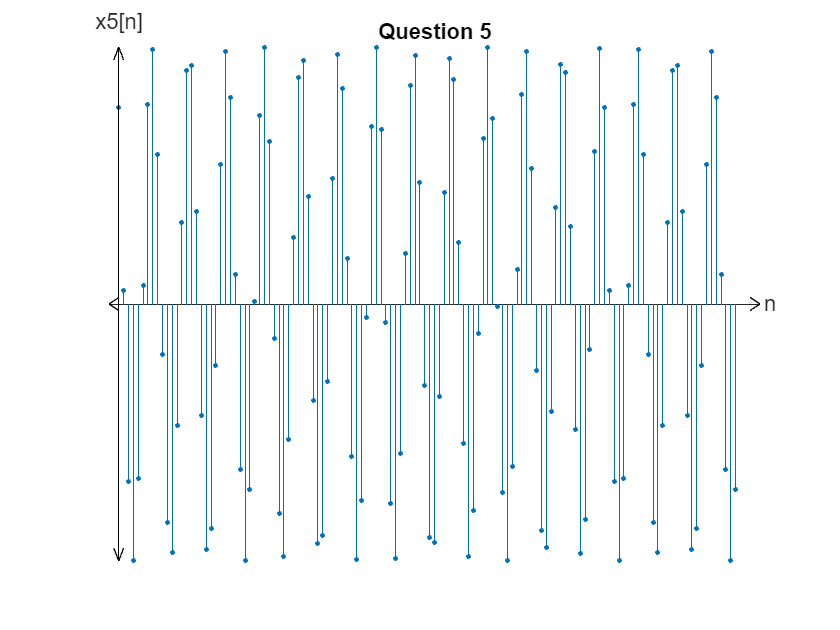

stem(n,x5,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x5[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 5');
hold off

$\omega =0\ldotp 26\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200}{26}k=100\;$$


if we add N to any t we can see that they are identical:

txt5period = sprintf('x5[1] = %f = x5[101] = %f',cos(0.26*pi*1+0.7),cos(0.26*pi*101+0.7));
disp(txt5period)

x5[1] = 0.053956 = x5[101] = 0.053956


###     Comment on Questions 4 & 5:

The period and frequency of both signals are identical. However, we can see that the function in Q5 has a addition of 0.7. Therefore, the signals have the same frequency yet they are never equal. We could call this a phase shift in a continous signal. However, in discrete signals the values are not equal to each other between the signals in a single period therefore we cannot call this a phase shift in discrete signals.

##     Question 6:

Calculate the values and perform the write to and read from file operations:

x6 = cos(0.01*pi*n);
x6read = readwrite2file(x6,'6');
txt6 = sprintf('x6[3] = %f | x6[7] = %f | x6[114] = %f | x6[127] = %f ',x6read(4),x6read(8),x6read(115),x6read(128));
disp(txt6)

x6[3] = 0.995562 | x6[7] = 0.975917 | x6[114] = -0.904827 | x6[127] = -0.661312 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

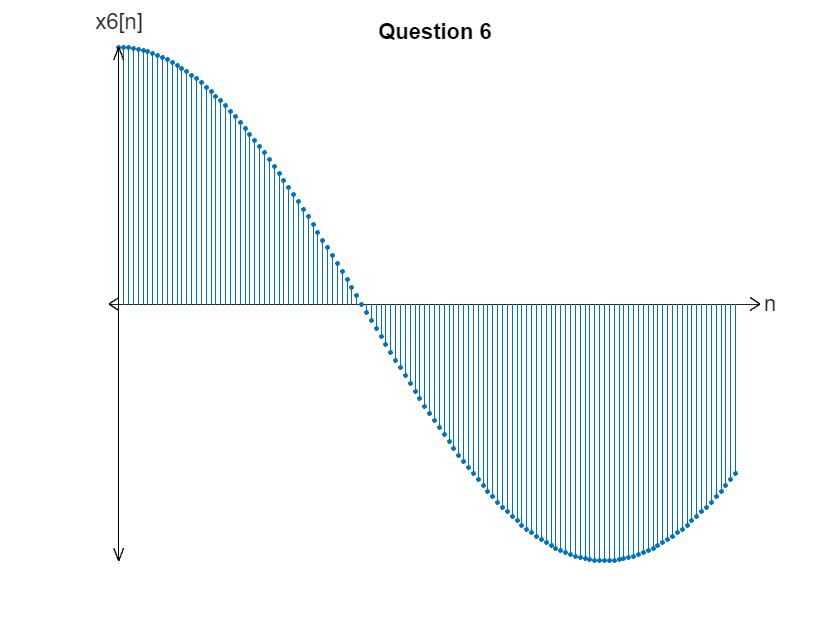

stem(n,x6,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x6[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 6');
hold off

$\omega =0\ldotp 01\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200}{1}k=200\;$$


if we add N to any t we can see that they are identical:

txt6period = sprintf('x6[1] = %f = x6[201] = %f',cos(0.01*pi*1),cos(0.01*pi*201));
disp(txt6period)

x6[1] = 0.999507 = x6[201] = 0.999507


##    Question 7:

Calculate the values and perform the write to and read from file operations:

x7 = cos(0.39*pi*n);
x7read = readwrite2file(x7,'7');
txt7 = sprintf('x7[3] = %f | x7[7] = %f | x7[114] = %f | x7[127] = %f ',x7read(4),x7read(8),x7read(115),x7read(128));
disp(txt7)

x7[3] = -0.860742 | x7[7] = -0.661312 | x7[114] = 0.125333 | x7[127] = 0.094108 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

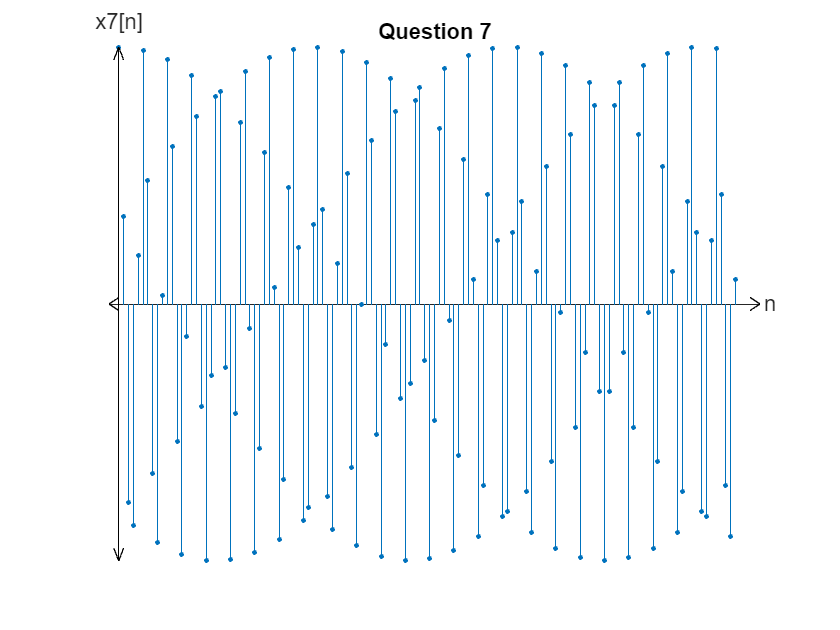

stem(n,x7,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x7[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 7');
hold off

$\omega =0\ldotp 39\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200}{39}k=200$$


if we add N to any t we can see that they are identical:

txt7period = sprintf('x7[1] = %f = x7[201] = %f',cos(0.39*pi*1),cos(0.39*pi*201));
disp(txt7period)

x7[1] = 0.338738 = x7[201] = 0.338738


##     Comment on Questions 6 & 7:

The frequency increased going from Q6 to Q7. This increase in frequency can be observed as the signal getting squeezed by a factor of 39.

##     Question 8:

Calculate the values and perform the write to and read from file operations:

x8 = cos(pi*n);
x8read = readwrite2file(x8,'8');
txt8 = sprintf('x8[3] = %f | x8[7] = %f | x8[114] = %f | x8[127] = %f ',x8read(4),x8read(8),x8read(115),x8read(128));
disp(txt8)

x8[3] = -1.000000 | x8[7] = -1.000000 | x8[114] = 1.000000 | x8[127] = -1.000000 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

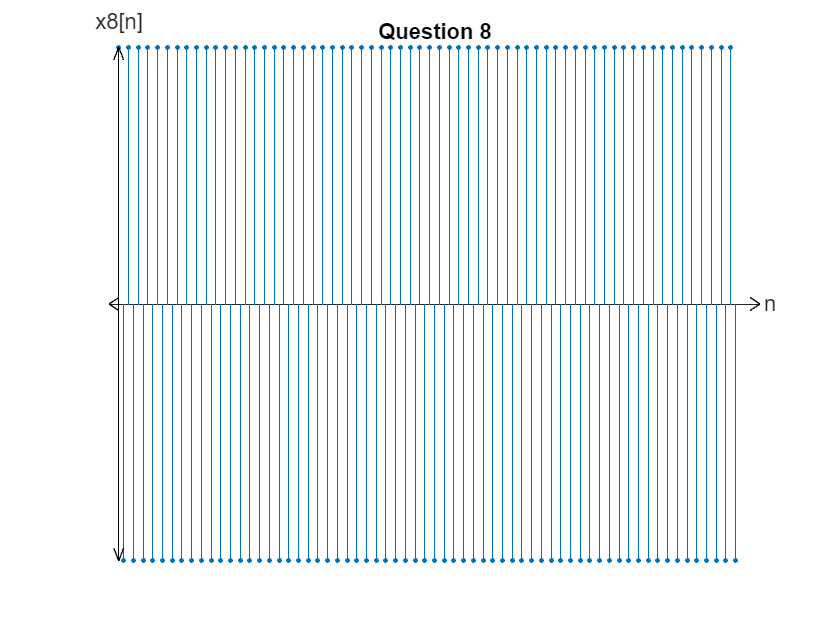

stem(n,x8,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x8[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 8');
hold off

$\omega =\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;2\pi \;}{\pi \;}k=2\;\;$$


if we add N to any t we can see that they are identical:

txt8period = sprintf('x8[1] = %f = x8[3] = %f',cos(pi*1),cos(pi*3));
disp(txt8period)

x8[1] = -1.000000 = x8[3] = -1.000000


##     Comment on Question 8:

The period of 2 is the smallest possible fundamental period that can be observed in a discrete signal. This is because 1 is the smallest possible change in discrete signals and it would take at least a difference of 't = 2' to change its value and return to the start. Any increase in frequency beyond this point would increase the period since it would not 'line up' with the integer intervals.

##     Question 9:

Calculate the values and perform the write to and read from file operations:

x9 = cos(1.08*pi*n);
x9read = readwrite2file(x9,'9');
txt9 = sprintf('x9[3] = %f | x9[7] = %f | x9[114] = %f | x9[127] = %f ',x9read(4),x9read(8),x9read(115),x9read(128));
disp(txt9)

x9[3] = -0.728969 | x9[7] = 0.187381 | x9[114] = -0.929776 | x9[127] = -0.876307 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

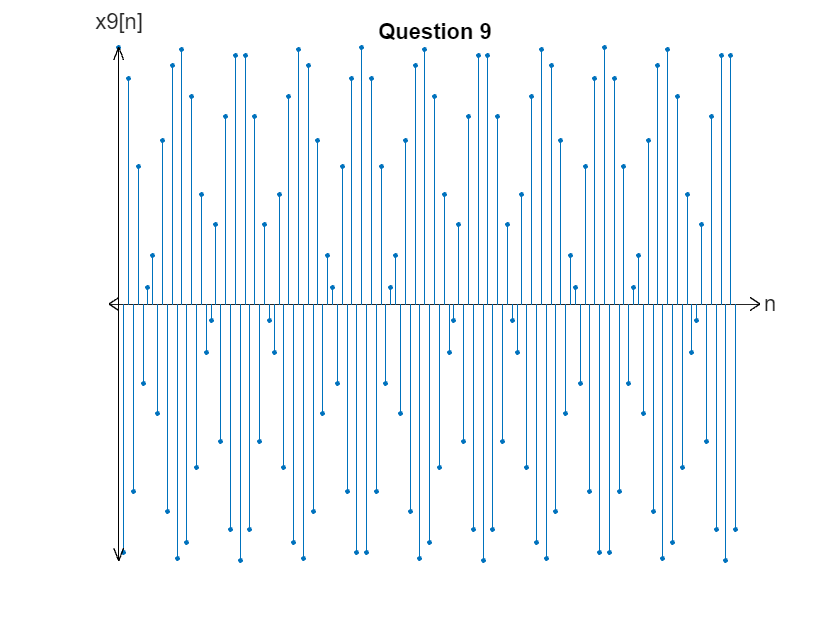

stem(n,x9,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x9[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 9');
hold off

$\omega =1\ldotp 08\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200\;}{108\;}k=50\;$$


if we add N to any t we can see that they are identical:

txt9period = sprintf('x9[1] = %f = x9[201] = %f',cos(1.08*pi*1),cos(1.08*pi*51));
disp(txt9period)

x9[1] = -0.968583 = x9[201] = -0.968583


##     Question 10:

Calculate the values and perform the write to and read from file operations:

x10 = cos(0.92*pi*n);
x10read = readwrite2file(x10,'10');
txt10 = sprintf('x10[3] = %f | x10[7] = %f | x10[114] = %f | x10[127] = %f ',x10read(4),x10read(8),x10read(115),x10read(128));
disp(txt10)

x10[3] = -0.728969 | x10[7] = 0.187381 | x10[114] = -0.929776 | x10[127] = -0.876307 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

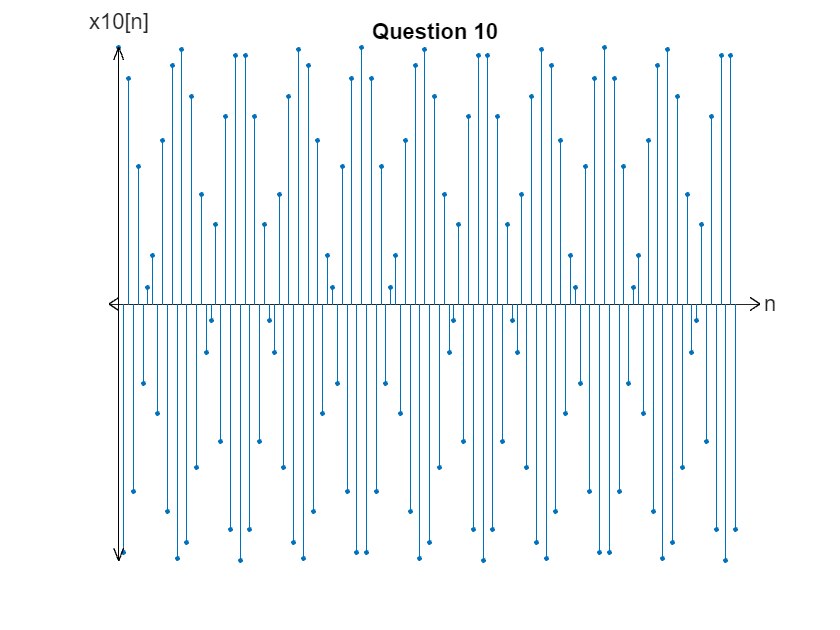

stem(n,x10,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x10[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 10');
hold off

$\omega =0\ldotp 92\pi \;\textrm{rad}\;$however this is a discrete signal. Therefore to compute the value of $N\;$we can do the following calculations:


$$N=\frac{\;200\;}{92}k=50$$


if we add N to any t we can see that they are identical:

txt10period = sprintf('x10[1] = %f = x10[51] = %f',cos(0.92*pi*1),cos(0.92*pi*51));
disp(txt10period)

x10[1] = -0.968583 = x10[51] = -0.968583


###     Comment on Questions 9 & 10:

We can notice that the values printed for $x_9 \left\lbrack 1\right\rbrack =x_{10} \left\lbrack 1\right\rbrack \;\textrm{and}\;x_9 \left\lbrack 51\right\rbrack =x_{10} \left\lbrack 51\right\rbrack$. If we plot the difference of the two signals we can see that it is 0 (the order of the y-axis is ${10}^{-14} \;$which is the result of floating point arithmetic errors). We can then conclude that the two discrete signals are equal. This can be proved with the following operations:

Assume we have two functions:

$f\left(t\right)=\cos \left(\left(n+d\right)\pi \;t\right)\;,\;g\left(t\right)=\cos \left(\left(n-d\right)\pi \;t\right)$ where $n\in N,d\in R$.   In our case $n=1,d=0\ldotp 08$

Since $\cos$ is an even function we can rewrite $g\left(t\right)$ as:


$$g\left(t\right)=\cos \left(\left(d-n\right)\pi \;t\right)$$


Now using change of variables, let $d=u+n$. Then our functions become:


$$f\left(t\right)=\cos \left(\left(u+2n\right)\pi \;t\right)=\cos \left(u\;\pi \;t+2n\;\pi \;t\right)\;,\;g\left(t\right)=\cos \left(u\;\pi \;t\right)$$


if $\frac{\;n}{t}\in N$, then $f\left(t\right)=g\left(t\right)$. In our case $t\in N\ldotp$ Therefore, $\cos \left(0\ldotp 92\pi \;t\right)=\cos \left(1\ldotp 08\pi \;t\right),\forall t\in N$

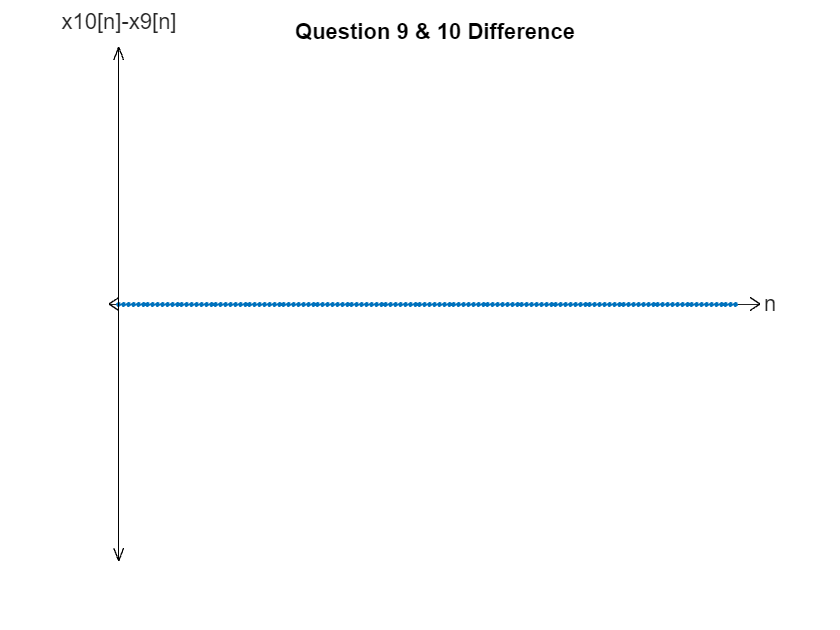

stem(n,x10-x9,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x10[n]-x9[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 9 & 10 Difference')
hold off

##     Question 11:

Calculate the values and perform the write to and read from file operations:

x11 = cos(n);
x11read = readwrite2file(x11,'11');
txt11 = sprintf('x11[3] = %f | x11[7] = %f | x11[114] = %f | x11[127] = %f ',x11read(4),x11read(8),x11read(115),x11read(128));
disp(txt11)

x11[3] = -0.989992 | x11[7] = 0.753902 | x11[114] = 0.619521 | x11[127] = 0.232359 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

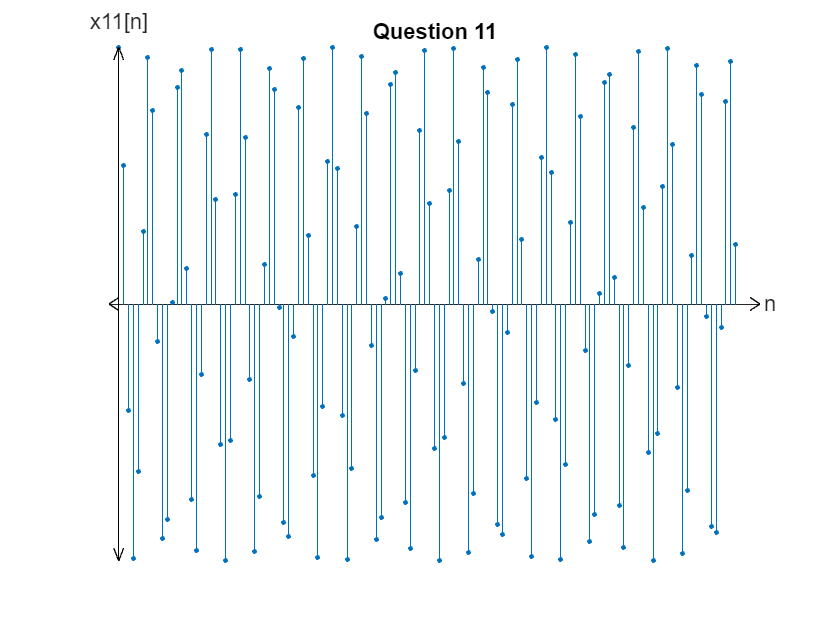

stem(n,x11,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x11[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 11');
hold off

$\omega =1\textrm{rad}$however, since the ratio of $\frac{\;2\pi \;}{1}$ isn't rational this signal isn't periodic.

##     Question 12:

Calculate the values and perform the write to and read from file operations:

x12 = cos(0.9*n+0.3);
x12read = readwrite2file(x12,'12');
txt12 = sprintf('x12[3] = %f | x12[7] = %f | x12[114] = %f | x12[127] = %f ',x12read(4),x12read(8),x12read(115),x12read(128));
disp(txt12)

x12[3] = -0.989992 | x12[7] = 0.950233 | x12[114] = -0.716128 | x12[127] = 0.068079 


%the array indices are n+1 the function values since 
% values start from 0 and indices start from 1

Plot the function as a stem plot:

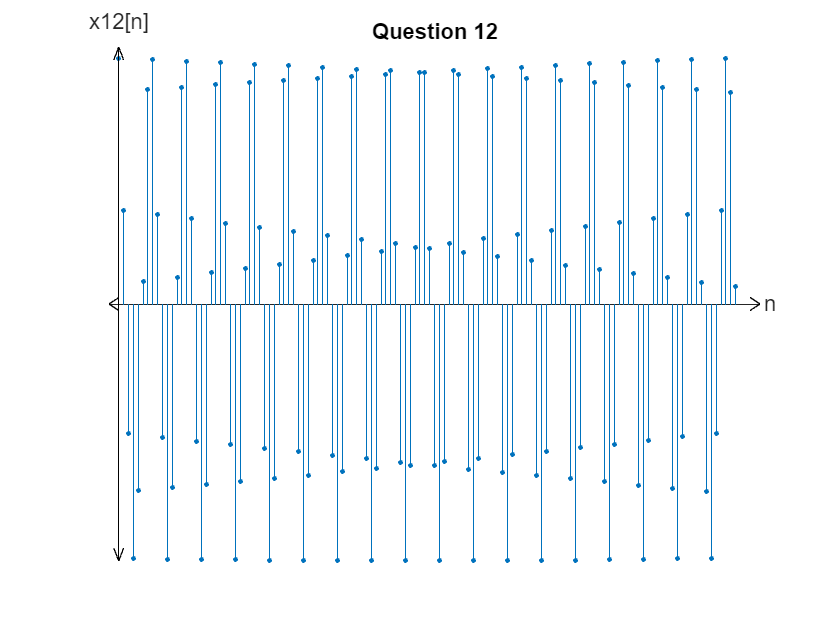

stem(n,x12,'filled','MarkerSize',2)
xlim([-2 132])
ylim([-1 1])

ax = gca;
axis(ax,'off')
set(get(ax,'XLabel'),'Visible','on')
set(get(ax,'YLabel'),'Visible','on')

hold on
plot([130 132],[0.025 0],'k')
plot([130 132],[-0.025 0],'k')
plot([-2 0],[0 0.025],'k')
plot([-2 0],[0 -0.025],'k')

plot([0 0],[-1 1],'k')
plot([-1 0],[0.95 1],'k')
plot([1 0],[0.95 1],'k')
plot([-1 0],[-0.95 -1],'k')
plot([1 0],[-0.95 -1],'k')

box off
label_h1 = xlabel('n');
label_h1.Position(1) = 134; % change horizontal position of ylabel.
label_h1.Position(2) = 0.05; % change vertical position of ylabel.

label_h2 = ylabel('x12[n]',rotation=0);
label_h2.Position(1) = 0; % change horizontal position of ylabel.
label_h2.Position(2) = 1.05; % change vertical position of ylabel.
title('Question 12');
hold off

$\omega =0\ldotp 9\textrm{rad}\;$however, since the ratio of $\frac{\;2\pi \;}{0\ldotp 9}$ isn't rational this signal isn't periodic.

##     Question 13:

The periods were provided under each question as equated to N.

##     Question 14:

$\omega \;$must be a an irrational number satisfying $\frac{\;2\pi \;}{\omega \;}\in Q$. The fundamental period is the smallest possible positive integer value of $\frac{\;2\pi \;}{\omega \;}k\in Z$ where $k\in Z$

##     Question 15:

Any continious sinusoidal wave is periodic. However in order for a discrete cos function to be contionus, it needs to satisfy the rules in Q14.

The reading and writing to file process function to be used repeatedly:

function xread = readwrite2file(x,num)
    filename = append('labvalues' , num ,'.txt');
    % open your file for writing
    file1 = fopen(filename,'wt');
    % write the matrix
    fprintf(file1,'%f\n',x');
    % close the file
    fclose(file1);
    
    % open your file for reading
    file1 = fopen(filename,'r');
    % write the matrix
    xread = fscanf(file1,'%f\n');
    % close the file
    fclose(file1);
end 